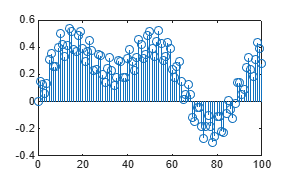

clear
clc
close all

%-------------------------------------------------------------------------
% Mixer project
% Code by Biel Yáñez Aranda
%-------------------------------------------------------------------------

%-------------------------------------------------------------------------
% Pt one: Generating the signal

% Frequencies of the signal

freq1 = 10000; % Hz
freq2 = 70;    % Hz
freq3 = 400;   % Hz
freq4 = 1000;  % Hz

% Sampling frequency
Fs = 44100;

% Number of samples
N = 44100;

% Generate time vector
n = 0:N-1;
t = n/Fs;

% Generating sampled waves
wave1 = 0.1 * sin(freq1 * 2 * pi * t);
wave2 = 0.4 * sin(freq2 * 2 * pi * t);
wave3 = 0.3 * sin(freq3 * 2 * pi * t);
wave4 = 0.2 * sin(freq4 * 2 * pi * t);

% White noise
noise = 0.005 * (2 * rand(1, N) - 1);

% Final signal
signal = wave1 + wave2 + wave3 + wave4 + noise;

stem(n,signal)
xlim([0,100])